# Polynominal and other functions

p = [1 2 -6 -8 10 4 0]

p =      1     2    -6    -8    10     4     0



x = linspace(-3,2,10000);

plot(x, polyval(p, x), 'b', 'LineWidth', 2)
grid on;

roots(p)

ans =          0
   -2.6855
   -2.0000
    1.7491
    1.2713
   -0.3349



pfunc = @(x) x.^6+2*x.^5-6*x.^4-8*x.^3+10*x.^2+4*x

pfunc = function_handle with value:
    @(x)x.^6+2*x.^5-6*x.^4-8*x.^3+10*x.^2+4*x



fsearch = @(x) pfunc(x)-exp(x)

fsearch = function_handle with value:
    @(x)pfunc(x)-exp(x)


xzero = fzero(fsearch, 1)

xzero = 1.0253

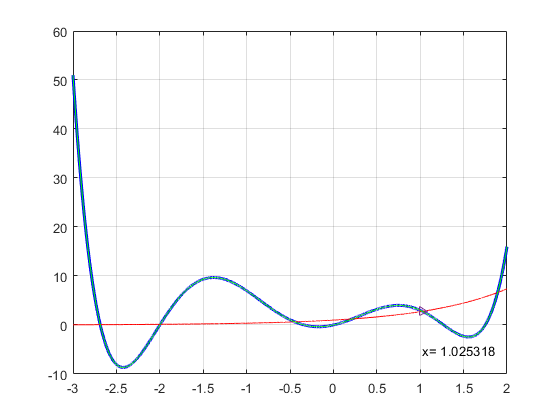


hold on
plot(x, exp(x), 'r')
plot(x, pfunc(x), 'g')
plot(xzero, exp(xzero), '>')
text(xzero, -5, sprintf('x= %f', xzero))

hold off